[X,T] = wine_dataset

X = 	1.0e+03 *

    0.0142    0.0132    0.0132    0.0144    0.0132    0.0142    0.0144    0.0141    0.0148    0.0139    0.0141    0.0141    0.0138    0.0147    0.0144    0.0136    0.0143    0.0138    0.0142    0.0136    0.0141    0.0129    0.0137    0.0129    0.0135    0.0131    0.0134    0.0133    0.0139    0.0140    0.0137    0.0136    0.0137    0.0138    0.0135    0.0135    0.0133    0.0131    0.0131    0.0142    0.0136    0.0134    0.0139    0.0132    0.0131    0.0142    0.0144    0.0139    0.0141    0.0139
    0.0017    0.0018    0.0024    0.0019    0.0026    0.0018    0.0019    0.0022    0.0016    0.0014    0.0022    0.0015    0.0017    0.0017    0.0019    0.0018    0.0019    0.0016    0.0016    0.0031    0.0016    0.0038    0.0019    0.0016    0.0018    0.0020    0.0018    0.0017    0.0019    0.0017    0.0015    0.0017    0.0018    0.0015    0.0018    0.0018    0.0016    0.0016    0.0015    0.0040    0.0017    0.0038    0.0019    0.0040    0.0018    0.0040    0.0036    0.0017   

T =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0



hiddenSize = 10;
autoenc1 = trainAutoencoder(X, hiddenSize, ...
    'L2WeightRegularization', 0.001,...
    'SparsityRegularization', 4,...
    'SparsityProportion', 0.05,...
    'DecoderTransferFunction','purelin');


features1 = encode(autoenc1,X);

hiddenSeze = 10;
autoenc2 = trainAutoencoder(features1, hiddenSize, ...
    'L2WeightRegularization', 0.001,...
    'SparsityRegularization', 4,...
    'SparsityProportion', 0.05,...
    'DecoderTransferFunction','purelin',...
    'ScaleData', false);

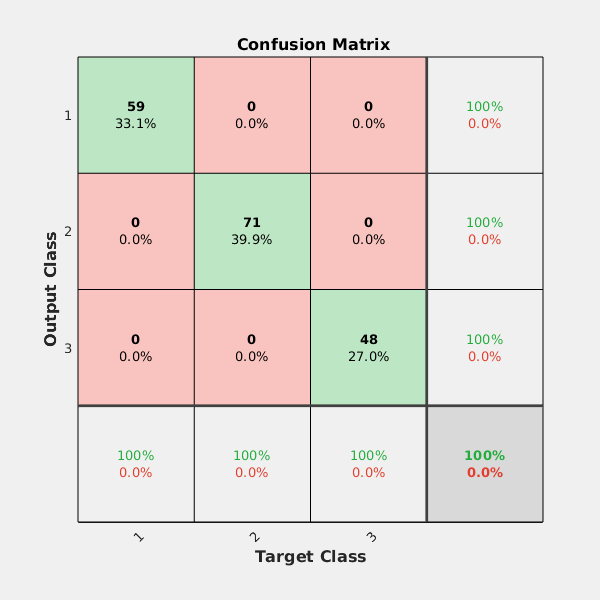

features2 = encode(autoenc2,features1);

softnet = trainSoftmaxLayer(features2,T,'LossFunction','crossentropy');
deepnet = stack(autoenc1,autoenc2,softnet);
deepnet = train(deepnet,X,T);

wine_type = deepnet(X);

plotconfusion(T,wine_type);